Рассмотрим сигнал как произведение одиночного прямоугольного импульса с единичной амплитудой и косинуса:


$$X(t) = \Pi (t) \cdot E\cos (2 \pi \frac{f_0} {2} t)$$
 

Тогда спектр произведения это свёртка спектров:


$$ET/2 \cdot \int_{-\inf}^{+inf} \frac{\sin (\pi (f - v)T)}{\pi (f - v)T} \cdot [\delta (v - f_0/2) + \delta (v + f_0/2)] dv = \frac{ET}{2} (sinc (\pi (f - f_0/2)T) + sinc (\pi (f + f_0/2)T))$$


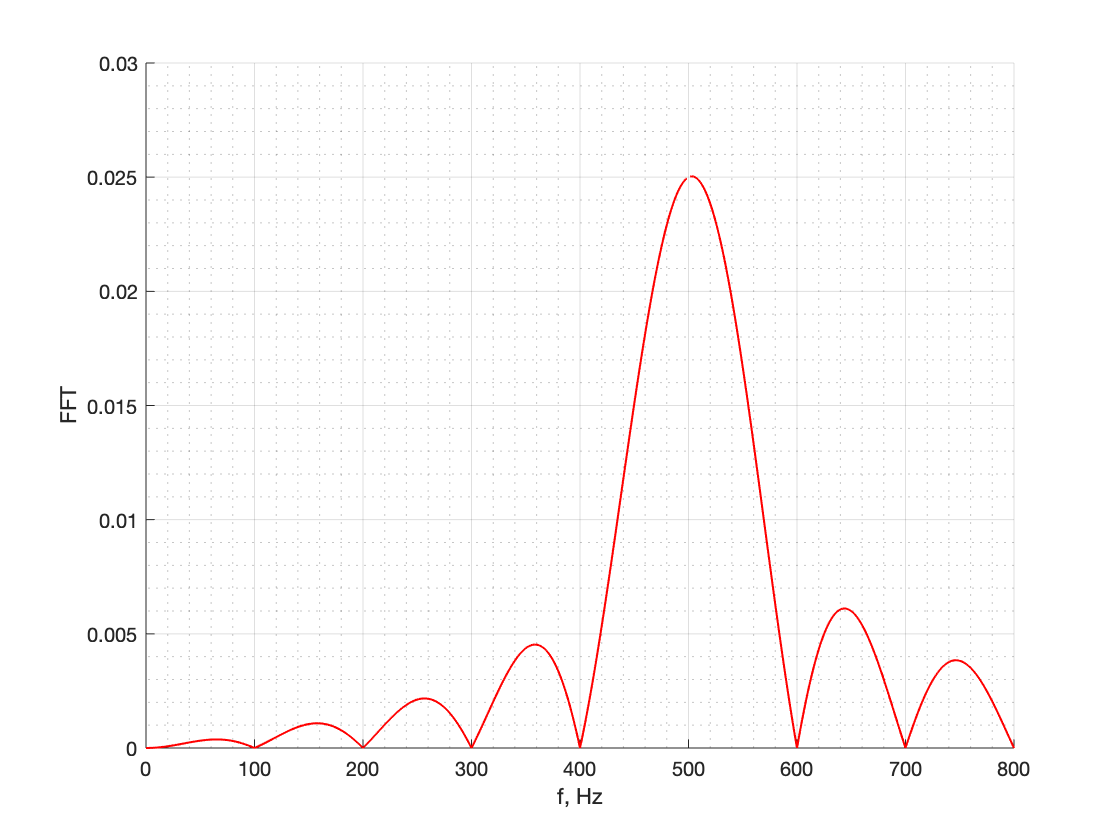

E=5;
f0=1*10^2;      
T=1/f0;         
f=linspace(0, 8*f0, 513);
t=linspace(0, 2*T, 513);

y = E.*T./2.*(sin(pi.*(f-f0/.2).*T)./(pi.*(f-f0/.2).*T) + sin(pi.*(f+f0/.2).*T)./(pi.*(f+f0/.2).*T));

%Спектры результирующих сигналов
figure('name', 'FFT'); 
grid on;
grid minor;
hold on;
plot(f, abs(y), 'r', 'LineWidth', 1);
hold off;
xlabel('f, Hz'); ylabel('FFT');

Итого, 0.0205